%Initialize all kernels from manual
Iden = [0 0 0;...
        0 1 0;...
        0 0 0]

Iden =      0     0     0
     0     1     0
     0     0     0


Gblur = (1/16)*...
        [1 2 1;...
        2 4 2;...
        1 2 1]

Gblur =     0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625


Sharp = [0 -1 0;...
        -1 5 -1;...
        0 -1 0]

Sharp =      0    -1     0
    -1     5    -1
     0    -1     0


VertSob = [1 0 -1;...
           2 0 -2;...
           1 0 -1]

VertSob =      1     0    -1
     2     0    -2
     1     0    -1


HorSob = [1 0 -1;...
           2 0 -2;...
           1 0 -1]

HorSob =      1     0    -1
     2     0    -2
     1     0    -1


%Acquire image and place on your current directory
%read the image using imread() and store it into a variable
I = imread('lena_gray', 'tiff');
%Convert image to greyscale
Igs = im2gray(I)

Igs = 512×512 uint8 matrix
   162   162   162   161   162   156   163   160   164   161   162   160   155   163   159   155   157   156   161   161   154   156   154   157   155   157   155   152   156   154   154   156   154   158   155   160   158   166   160   166   166   166   166   172   171   175   173   170   172   172
   162   162   162   161   162   156   163   160   164   161   162   160   155   163   159   155   157   156   161   161   154   156   154   157   155   157   155   152   156   154   154   156   154   158   155   160   158   166   160   166   166   166   166   172   171   175   173   170   172   172
   162   162   162   161   162   156   163   160   164   161   162   160   155   163   159   155   157   156   161   161   154   156   154   157   155   157   155   152   156   154   154   156   154   158   155   160   158   166   160   166   166   166   166   172   171   175   173   170   172   172
   162   162   162   161   162   156   163   160   164   161   162   1

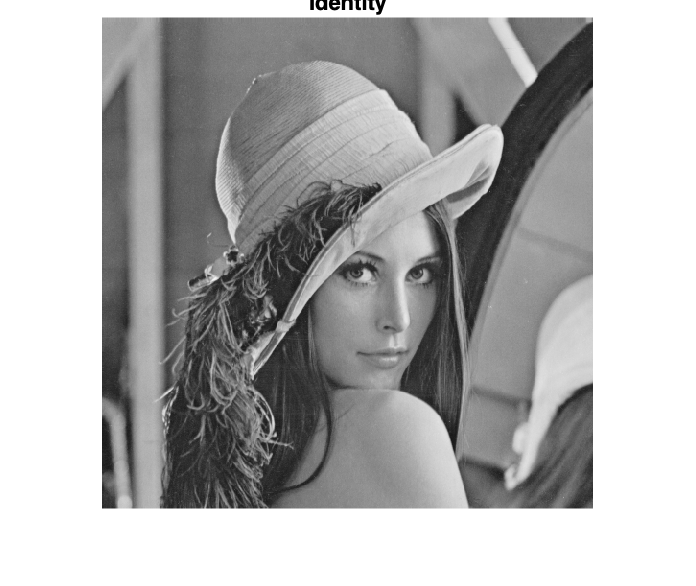


%Filter images
Idenfil = uint8(imfilter(Igs, Iden));
Igbfil = uint8(imfilter(Igs, Gblur));
Ishfil = uint8(imfilter(Igs, Sharp));
Ivsfil = uint8(imfilter(Igs, VertSob));
Ihsfil = uint8(imfilter(Igs, HorSob));
figure(1)
imshow(Idenfil); title('Identity')

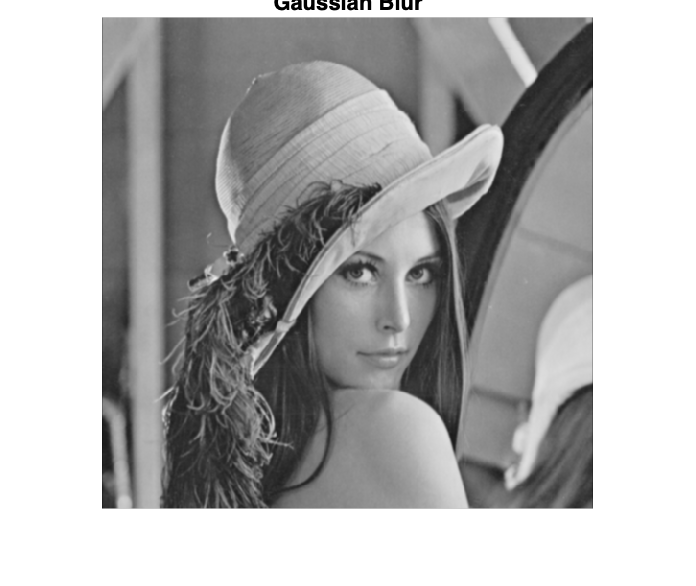

imshow(Igbfil); title('Gaussian Blur')

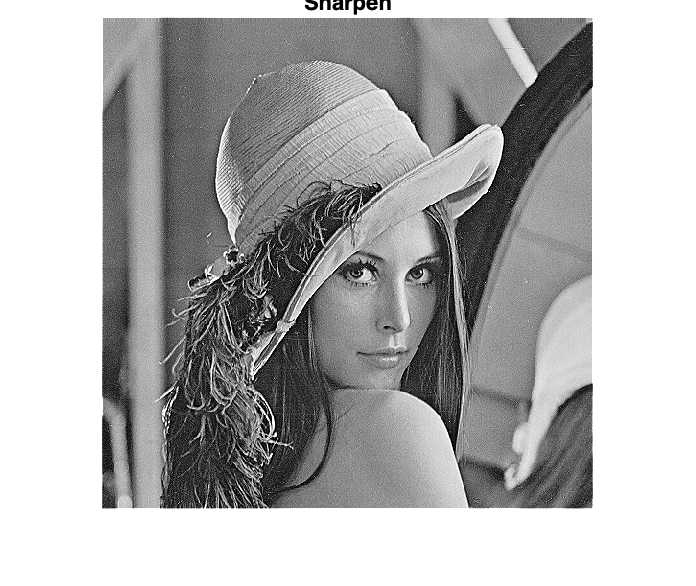

imshow(Ishfil); title('Sharpen')

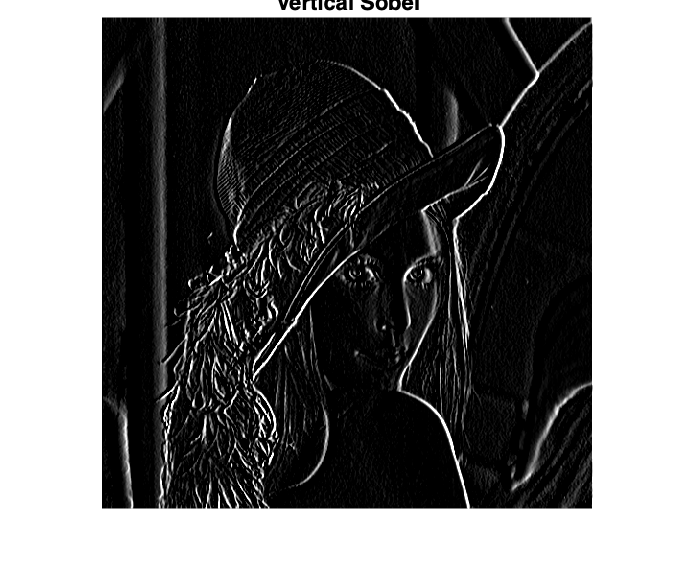

imshow(Ivsfil); title('Vertical Sobel')

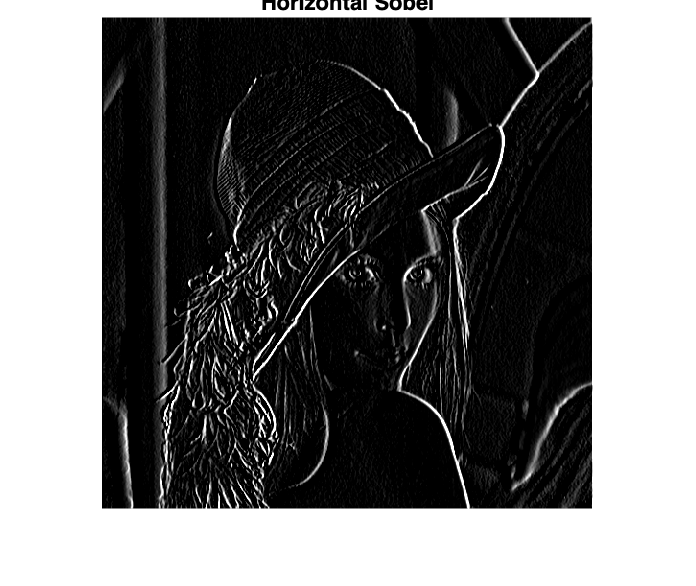

imshow(Ihsfil); title('Horizontal Sobel')